# Proyecto de ciencia de los datos

## Universidad Autónoma del Estado de México

## CU UAEM Zumpango

## Ingeniería en Computación

## Ciencia de los Datos

## Integrantes:

### Sofia Omara Guerrero Angeles

### Ivan Eduardo Andrade Ruiz

### Renata Montserrat Andrade Ruiz

## Profesor: Asdrúbal López Chau

## 22 Noviembre 2022

## Conjunto de datos

El siguiente conjunto de datos fué recolectado de la base de datos [Efectos del alcohol en el estudio | Kaggle](https://www.kaggle.com/datasets/whenamancodes/alcohol-effects-on-study), dichos datos reflejan el rendimiento estudiantil en la educación secundaria de dos escuelas portuguesas.  Los atributos de los datos incluyen calificaciones de los estudiantes, características demográficas, sociales y relacionadas con la escuela, los cuales fueron recolectados mediante el uso de informes y cuestionarios escolares. Dicha base de datos proporciona dos conjuntos de datos sobre el rendimiento en dos asignaturas distintas: Matemáticas (mat) y lengua portuguesa (por); sin embargo, el conjunto de datos seleccionado para llevar a cabo el análisis fue únicamente de la asignatura de Matemáticas. 

## Preguntas 

1) ¿Qué factores provocan que el alumno ingiera bebidas alcoholicas?

+Exploratoria

2) ¿De qué manera influye el estado de convivencia de los padres con el consumo de alcohol de los estudiantes?

+Exploratoria

3) ¿El sexo influye en la cantidad del alcohol consumido?

+Inferencial

4) ¿El alcohol afecta el desempeño académico de los estudiantes?

+Inferencial

5) ¿La salud de los jovenes decae con el consumo de alcohol?

+Exploratoria

6) ¿Estar dentro de una relación disminuye el consumo de alcohol?

+Inferencial

7) ¿La calidad de la relación con la familia es un detonante para consumir alcholol?

+Inferencial

**Exploratoria. **Enfocada, observar si existe alguna asociación, patrón o tendencias en las variables. Permite formular hipótesis que después hay que comprobar.

**Inferencial**. Permite afirmar o rechazar una hipótesis planteada. Se usan distintos conjuntos de datos para concluir que la hipótesis es cierta/falsa en general.

Son buenas preguntas ya que cumplen con las características que deben tener las preguntas para el estudio de los datos, las cuales son:

*Interesante. Son de gran interés, ya que, son temas importantes para conocer la razón del consumo del alcohol de los adolescentes.

*No respondida anteriormente. Este tipo de temas no se tocan con gran frecuencia.

*Pausible. Genera interés pues son preguntas precisas y concisas.

*Factible. Si se pueden responder con el conjunto de datos que se tiene.

*Específica. Son preguntas muy concretas.

Los metodos usados para responder estas preguntas fueron:

+**Histogramas.** Los histogramas permiten obtener una visión general de la distribución existente en una muestra de datos. Para lo que dibuja barras asociadas a un rango de valores, siendo la altura de estas proporcional a la frecuencia de aparición de estos.

+**Scatter.** Se utilizan para observar la relación entre las variables y utilizan puntos para representar la relación entre ellas. El método scatter() en la biblioteca matplotlib se usa para dibujar un diagrama de dispersión. Los diagramas de dispersión se usan ampliamente para representar la relación entre variables y cómo el cambio en uno afecta al otro.  

+**Gscatter.** Crea una gráfica de dispersión de `x` e `y`, agrupada por `g`. Los datos de entrada `x` e `y` son vectores del mismo tamaño.

+**Chi cuadrada.** Prueba la hipótesis nula de que los datos categóricos tienen las frecuencias dadas.

## Análisis Exploratorio

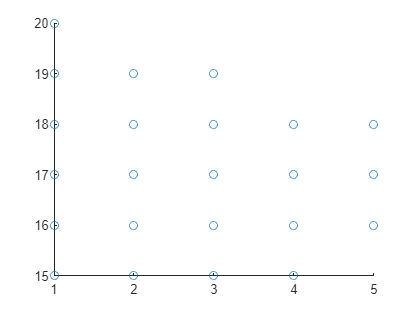

%leemos los datos
x = readtable("Maths.csv");
%Graficamos Alcohol consumido el fin de semana vs Edad, agrupado por Genero
idx = x.sex=="F";
scatter(x.Walc(idx), x.age(idx))

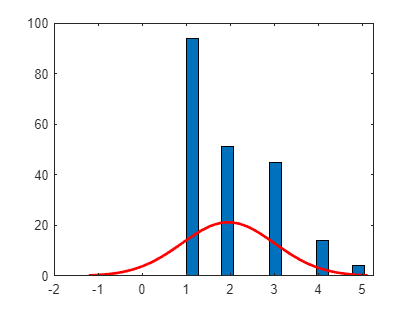

histfit(x.Walc(idx))   %hacemos un histograma para visualizar cuanto alcohol consumen las mujeres el fin de semana

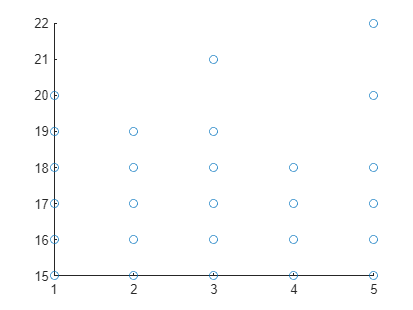

idx = x.sex=="M";
scatter(x.Walc(idx), x.age(idx))

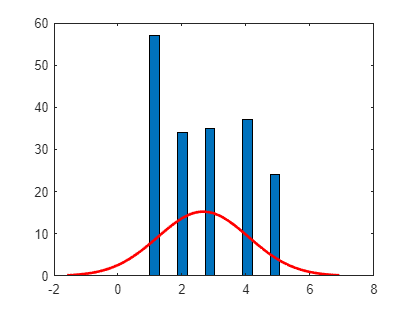

histfit(x.Walc(idx))   %hacemos un histograma para visualizar cuanto alcohol consumen los hombres el fin de semana

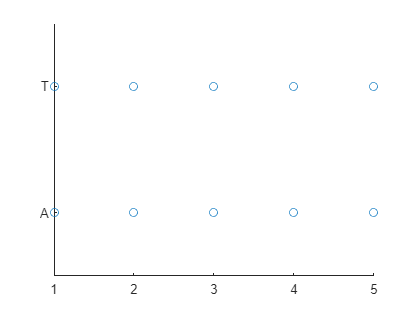

scatter(x.Walc, categorical(x.Pstatus))

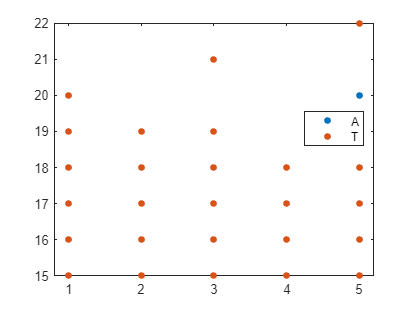

gscatter(x.Walc, x.age, categorical(x.Pstatus))

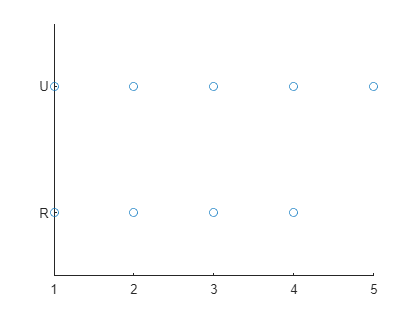

idx = x.Pstatus=="A";   %graficamos la cantidad de alcohol consumida y la zona por los padres que viven separados
scatter(x.Walc(idx), categorical(x.address(idx)))

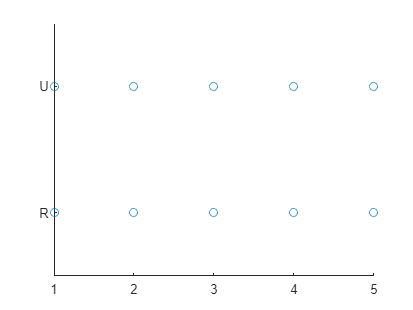

idx = x.Pstatus=="T";   %graficamos la cantidad de alcohol consumida y la zona por los padres que viven juntos
scatter(x.Walc(idx), categorical(x.address(idx)))

## Análisis de los datos

### Análisis Estatus social vs Alcohol consumido

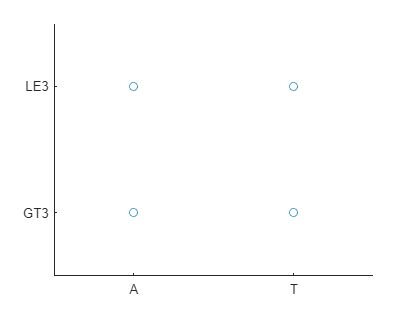

%graficamos el estatus de los padres con el tamaño de la familia
scatter(categorical(x.Pstatus), categorical(x.famsize))

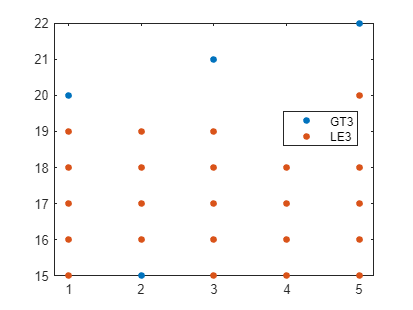

gscatter(x.Walc, x.age, categorical(x.famsize))

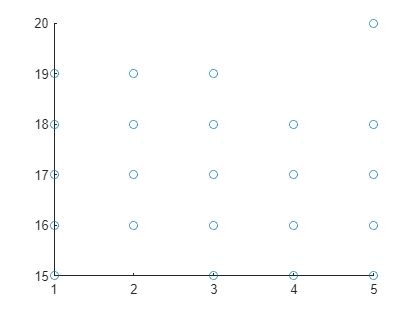

idx = x.famsize=="LE3";   %graficamos la cantidad de alcohol consumida y el numero de integrantes con los que cuenta la familia(LE3-> menos de 3)
scatter(x.Walc(idx), x.age(idx))

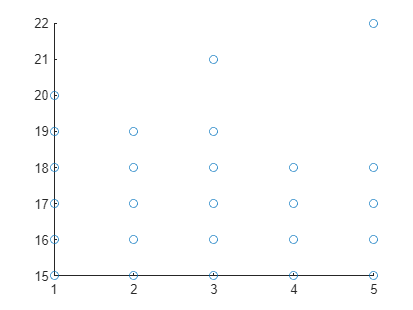

idx = x.famsize=="GT3";   %graficamos la cantidad de alcohol consumida y el numero de integrantes con los que cuenta la familia(GT3-> mas de 3)
scatter(x.Walc(idx), x.age(idx))

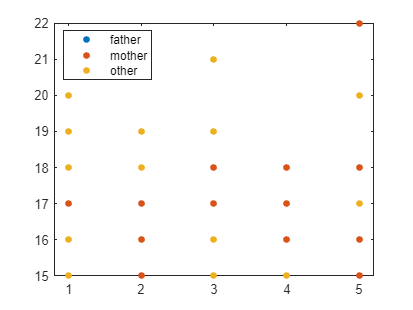

%graficamos el tutor de los jovenes con la cantidad de alcohol consumida y
%la edad
gscatter(x.Walc, x.age, categorical(x.guardian))

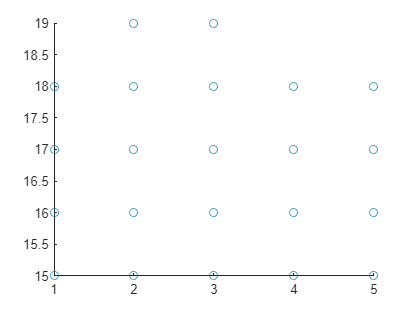

idx = x.guardian=="father";   %graficamos la cantidad de alcohol consumida y el tutor del alumno (padre)
scatter(x.Walc(idx), x.age(idx))

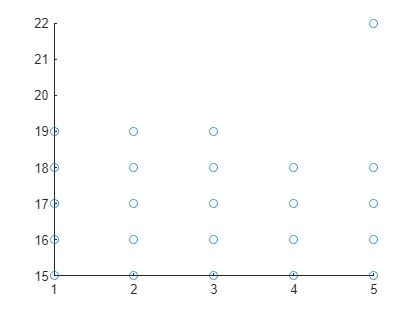

idx = x.guardian=="mother";   %graficamos la cantidad de alcohol consumida y tutor del alumno(madre)
scatter(x.Walc(idx), x.age(idx))

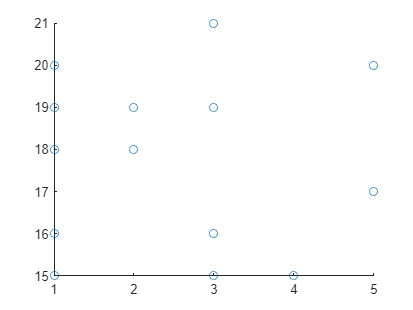

idx = x.guardian=="other";   %graficamos la cantidad de alcohol consumida y tutor del alumno(otro)
scatter(x.Walc(idx), x.age(idx))

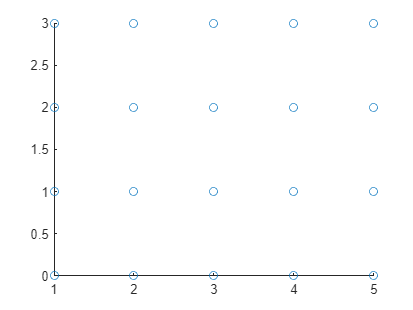

scatter(x.Walc, x.failures)   %graficamos numero de fallas con el alcohol consumido

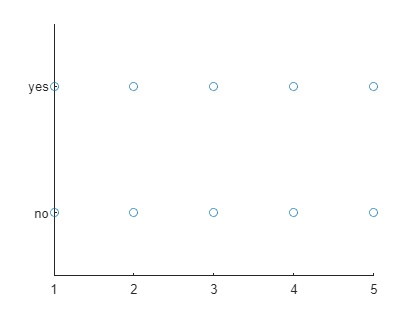

scatter(x.Walc, categorical(x.famsup))   %graficamos alcohol consumido con el apoyo familiar

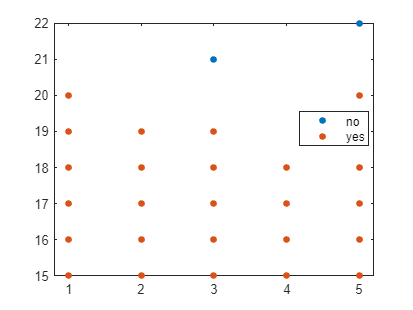

gscatter(x.Walc, x.age, categorical(x.famsup))

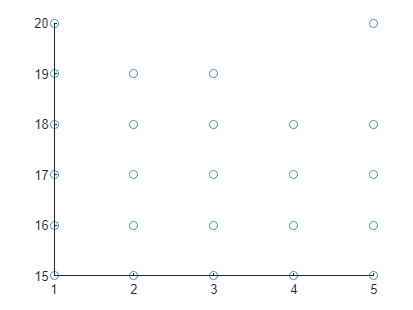

idx = x.famsup=="yes";  %graficamos alcohol consumido dependiendo de si el alumno recibe o no apoyo familiar
scatter(x.Walc(idx), x.age(idx))

idx = x.famsup=="no";  %graficamos alcohol consumido dependiendo de si el alumno recibe o no apoyo familiar
scatter(x.Walc(idx), x.age(idx))

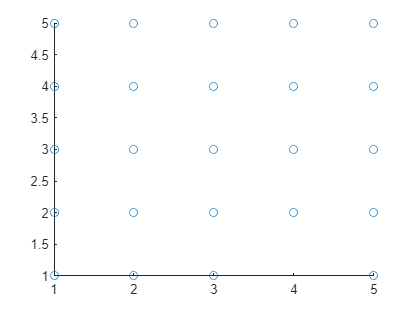

scatter(x.Walc, x.freetime)   %graficamos el alcohol consumido con el tiempo libre del estudiante

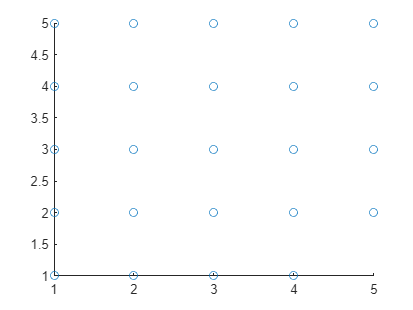

scatter(x.Walc, x.goout)    %graficamos el alcohol consumido con la frecuencia de la salida con amigos

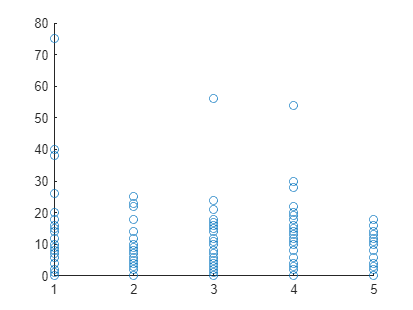

scatter(x.Walc, x.absences)    %graficamos el alcohol con las ausencias regitradas-> ¿como sacar promedio de faltas por el alcohol consumido?

scatter(x.Walc, categorical(x.romantic))   %graficamos alcohol consumido respecto a si se encuentra en una relacion romantica o no

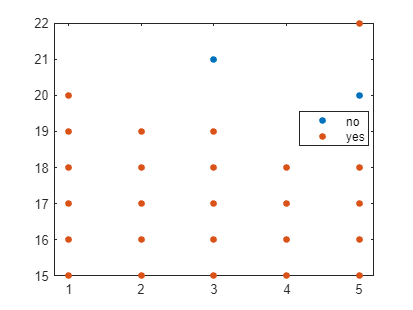

gscatter(x.Walc, x.age, categorical(x.romantic))    %graficamos edad y alcohol consumido agrupando por situacion romantica

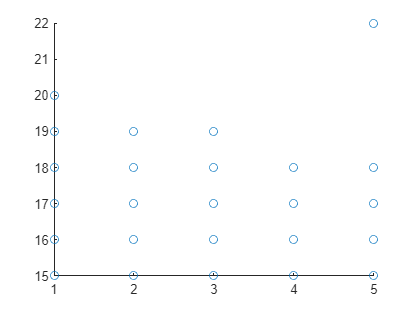

idx = x.romantic=="yes";  %graficamos alcohol consumido dependiendo de si el alumno esta o no en una relacion amorosa
scatter(x.Walc(idx), x.age(idx))

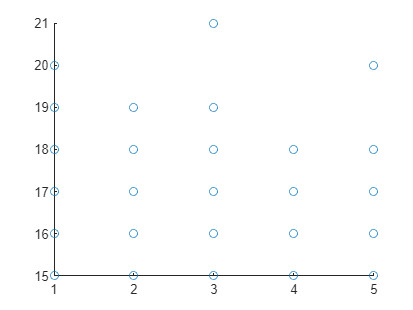

idx = x.romantic=="no";  %graficamos alcohol consumido dependiendo de si el alumno NO esta en una relacion amorosa
scatter(x.Walc(idx), x.age(idx))

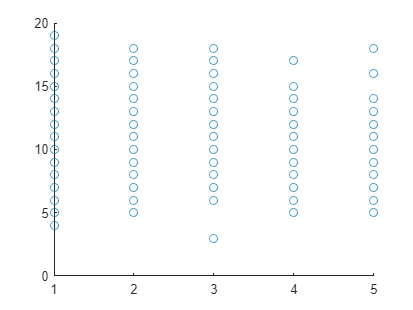

scatter(x.Walc, x.G1)   %graficamos consumo del alcohol con las notas del 1er periodo

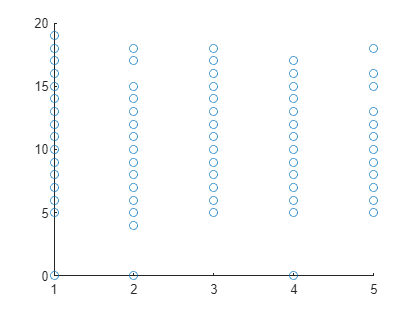

scatter(x.Walc, x.G2)   %graficamos consumo del alcohol con las notas del 2do periodo

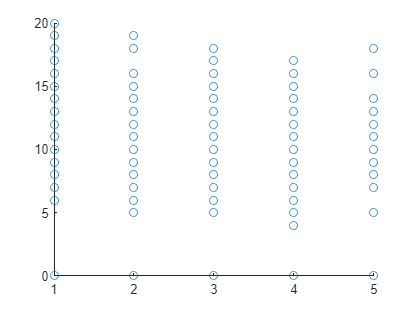

scatter(x.Walc, x.G3)   %graficamos consumo del alcohol con las notas del 3er periodo

### Análisis de salud vs alcohol consumido

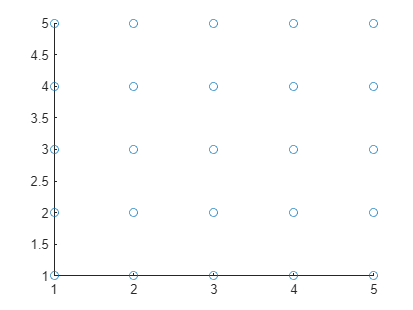

scatter(x.Walc, x.health)    %graficamos la cantidad de alcohol consumido en relacion a la salud de los estudiantes

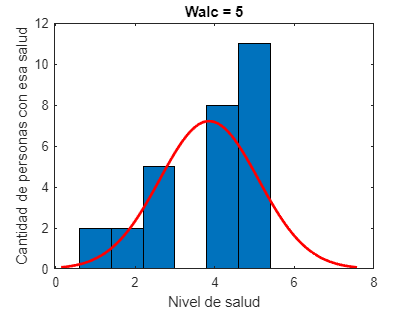

idx = x.Walc==5;   %maxima cantidad de alcohol consumida
histfit(x.health(idx))   %hacemos un histograma para visualizar la salud de aquellos que beben mucho en fines de semana
title("Walc = 5")
xlabel("Nivel de salud")
ylabel("Cantidad de personas con esa salud")

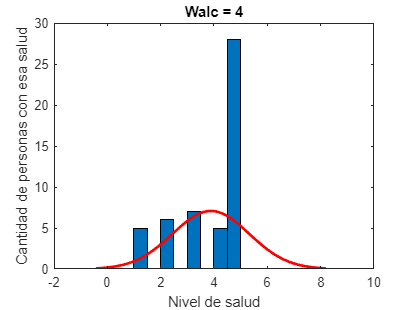

idx = x.Walc==4; 
histfit(x.health(idx))   %hacemos un histograma para visualizar la salud de aquellos que beben mucho en fines de semana
title("Walc = 4")
xlabel("Nivel de salud")
ylabel("Cantidad de personas con esa salud")

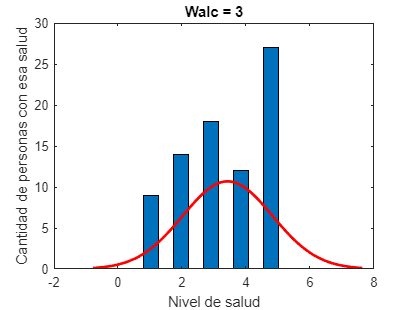

idx = x.Walc==3; 
histfit(x.health(idx))   %hacemos un histograma para visualizar la salud de aquellos que beben mucho en fines de semana
title("Walc = 3")
xlabel("Nivel de salud")
ylabel("Cantidad de personas con esa salud")

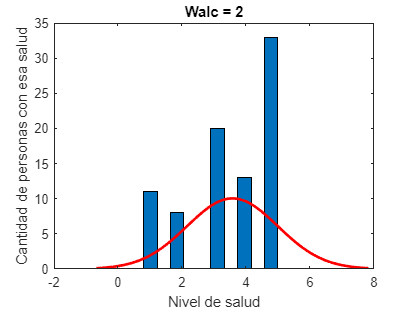

idx = x.Walc==2; 
histfit(x.health(idx))   %hacemos un histograma para visualizar la salud de aquellos que beben mucho en fines de semana
title("Walc = 2")
xlabel("Nivel de salud")
ylabel("Cantidad de personas con esa salud")

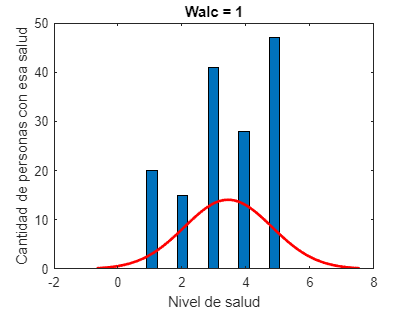

idx = x.Walc==1;     %Minima cantidad de alcohol consumida
histfit(x.health(idx))   %hacemos un histograma para visualizar la salud de aquellos que beben mucho en fines de semana
title("Walc = 1")
xlabel("Nivel de salud")
ylabel("Cantidad de personas con esa salud")

### Análisis Chi Cuadrada

x = readtable("Maths.csv");
%Ajuste Chi-Cuadrado
%tabla = grados de libertad chi2 = hipotesis nula 
% p = hipotesis alternativa < 0.05 se acepta >= 0.05 se rechaza
%Comparación: Bebida Fin de Semana // Salud 
%p alta[tabla,chi2,p] = crosstab(x.Walc,x.health)
%Comparación: Bebida Fin de Semana // Estado de la familia
%p alta[tabla,chi2,p] = crosstab(x.Walc,x.Pstatus)
%Comparación: Bebida Fin de Semana // Tamaño de la Familia
%p alta[tabla,chi2,p] = crosstab(x.Walc,x.famsize)
%Comparación: Bebida Fin de Semana // Tiempo de Traslado
[tabla,chi2,p] = crosstab(x.Walc,x.traveltime)

tabla =    101    44     5     1
    54    24     6     1
    54    21     5     0
    31    15     5     0
    17     3     2     6


chi2 = 63.3212

p = 5.5621e-09

%Comparación: Bebida Fin de Semana // Relaciones Amorosas
%p alta[tabla,chi2,p] = crosstab(x.Walc,x.romantic)
%Comparación: Bebida Fin de Semana // Tiempo Libre
[tabla,chi2,p] = crosstab(x.Walc,x.freetime)

tabla =     12    19    65    43    12
     2    27    34    16     6
     3     8    32    28     9
     0     8    15    22     6
     2     2    11     6     7


chi2 = 42.0810

p = 3.8377e-04

%Comparación: Bebida Fin de Semana // Acceso a Internet
[tabla,chi2,p] = crosstab(x.Walc,x.internet)

tabla =     28   123
    12    73
    13    67
     7    44
     6    22


chi2 = 1.5616

p = 0.8157

%Comparación: Bebida Fin de Semana // Dirección
%p alta[tabla,chi2,p] = crosstab(x.Walc,x.address)
%Comparación: Bebida Fin de Semana // Guardián
%p alta[tabla,chi2,p] = crosstab(x.Walc,x.guardian)
%Comparación: Bebida Fin de Semana // Sexo
[tabla,chi2,p] = crosstab(x.Walc,x.sex)

tabla =     94    57
    51    34
    45    35
    14    37
     4    24


chi2 = 37.3636

p = 1.5158e-07

### Promedios Estadísticos

%Promedio
%Promedio de alcohol que beben en fines de semana
W = mean(x.Walc)

W = 2.2911

%Salud promedio de los estudiantes
H = mean(x.health)

H = 3.5544

%Promedio de notas del 1er periodo de los estudiantes
N1 = mean(x.G1)

N1 = 10.9089

%Promedio de notas del 2do periodo de los estudiantes
N2 = mean(x.G2)

N2 = 10.7139

%Promedio de notas finales de los estudiantes
N3 = mean(x.G3)

N3 = 10.4152

Para el análisis del conjunto de datos anterior, no fue necesario llevar a cabo ninguna limpieza de los datos, debido a que éstos ya se encontraban estructurados y codificados dentro de los campos, lo que sí se realizó fué un análisis exhaustivo de los resultados obtenidos en las gráficas para ir descartando los atributos que eran irrelevantes para el análisis como lo son el sexo y la edad.

## Hallazgos

Durante el análisis exploratorio, se pudo notar que ni la edad ni el sexo influyen de forma determinante en el consumo del alcohol, debido a que las graficas obtenidas, muestran que los resultados se traslapan entre si, lo que quiere decir que estos dos atributos no permiten discriminar los datos significativamente para encontrar nuevos hallazgos, más sin embargo, se utilizó el atributo de la edad para poder analizar los demas atributos para realizar nuevos hallazgos. Como siguiente paso en este análisis, se creyó que el estado de los padres (si viven juntos->T o separados->A) podría influir en que el alumno consuma o no grandes cantidades de alcohol, por lo que al graficar dichos atributos se observó que en realidad consumen exactamente la misma cantidad de alcohol sin importar este hecho por lo que también fue deshechada la posibilidad de que este aspecto fuera un detonante para los jóvenes, mas sin embargo, fue un punto importante para el siguiente descubrimiento que se hizo a continuación, pues aunque el atributo por si solo no es un detonante para el consumo del alcohol en los jovenes, si es un antecedente importante a considerar, dicho esto, nos planetamos la hipotesis de que tal vez el consumo del alcohol sea mas elevado en zonas urbanas que en rurales, por lo que se realizaron las graficas de este aspecto tomando en cuenta el antecedente del estado de los padres, notando que en el caso donde los padres estaban juntos; el consumo del alcohol era invariable en ambas zonas, cosa que no sucedia en el caso donde los padres estaban separados, ya que se observó que en las zonas rurales, el consumo del alcohol no llegó a ser muy alto a diferencia de las zonas urbanas. 

Como siguiente hipótesis, nos planetamos la idea de que el tamaño de la familia podría ser un detonante para que los padres se separen, mas sin embargo, realizando el análisis por medio de la gráfica, nos dimos que cuenta que aunque sea una familia grande o pequeña, se presentan ambos casos donde los padres estan separados y juntos; sin embargo, se usó el atributo del tamaño de la familia para descartar la idea de que entre mas grande es la familia, mas propenso es el alcoholismo en los jovenes, por lo que al graficar la cantidad de alcohol consumido los fines de semana y la edad agrupados por el tamaño de la familia, nos pudimos dar cuenta que los datos se econtraban un poco dispersos con respecto a los realizados con anterioridad, notando que los jovenes que vivian con una familia grande consumían más alcohol que aquellos cuya familia era menor o igual a 3 integrantes.

Como siguiente hipotesis, nos planteamos la idea de que el consumo del alcohol podria estar relacionado con el tutor de los jovenes, el cual, se clasifica en padre, madre y otro; por lo que al realizar el análisis, se descubrió que no había gran diferencia de los resultados entre el padre y la madre, más sin embargo, se pudo observar que en el caso de que el tutor sea otro, el consumo del alcohol en algunos casos, se presentaba en una edad mas avanzada como es el caso del alcohol en nivel bajo cuya edad rondaba entre los 18 y 19, a diferencia de los resultados del padre y la madre que era entre los 15 y 19, tambien se observo esto en el caso del consumo alto de alcohol, donde solo se presento en la edad de 15 años, difiriendo del caso de la madre y padre que se presento entre los 15 y 18 años de edad, y en el caso del consumo muy alto de alcohol, aquellos jovenes que estaban bajo la custodia de otra persona, bebian mucho alcohol los de 17 y 20 años, cosa que sucedia desde los 15 a los 22 años en el caso de la madre y el padre; lo que nos quiere decir que aquellos jovenes que esta bajo el cuidado de otra persona, consume menos alcohol o empieza a consumirlo a una edad mas avanzada que aquellos jovenes que se encuentran bajo la custodia de sus padres.

Comprobamos si el alcohol tenía influencia en el nivel de fallas de las clases anteriores, pero al realizar el análisis de los datos, pudimos observar que invariablemente de cuanto alcohol consuman los jovenes, las fallas eran las mismas; tambien observamos que aquellos jovenes que no recibian apoyo familiar, tenian mas tendencia a beber mas alcohol que aquellos que recibian dicho apoyo pero, cabe mencionar, que dicha diferencia no era tan grande; tambien se observó que el tiempo libre con el que disponian  los jovenes no era un detonante para el consumo del alcohol, debido a que, bebian lo mismo si tenian mucho o poco tiempo disponible lo mismo sucedio con la frecuencia de las salidas con amigos, ya que, el alcohol consumido era el mismo si salian frecuentenemnte o no  con sus amigos, por lo que estos dos atributos fueron descartados como detonantes en el consumo del alcohol de los jóvenes. Un hallazgo que llamo nuestra atención, fué cuando graficamos las ausencias escolares en funcion del alcohol consumido; debido a que, nos dimos cuenta que el numero de inasistencias era elevado para aquellos que bebian poco alcohol, moderado para los que bebian regular y alto y relativamente bajo para aquellos que tenian un consumo de alcohol muy alto, dandonos a entender que las insasistencias podrian ser debido a otros factores (sin descartar la posibilidad de que parte de ellas hayan sido resultado del consumo del alcohol pero sin ser éste la causa principal de las inasistencias).

También, se creyó que el hecho de que los jovenes estén o no en una relacion romántica podría representar un detonante para que los jovenes consumieran alcohol, más sin embargo, una vez realizado el análisis se descartó esta posibilidad, ya que, el consumo del alcohol era el mismo para aquellos que estaban en una relación y aquellos que no lo estaban.

Durante las calificaciones, se pudo notar que en el 2do periodo, la mayoria de los jovenes bajo sus calificaciones con respecto al primer periodo, en el 3er periodo (que es la calificacion final), los jovenes que consumian muy bajo, bajo y regular alcohol durante los fines de semana, incrementaron sus notas, mientras que los que consumian alto y muy alto alcohol en los fines de semana, bajaron sus notas.

Para llevar a cabo el análisis correspondiente a la salud, en primer lugar, se realizo una grafica sencilla entre el nivel de salud y el alcohol consumido, observando que dicha grafica no mostraba los resultados en todo su panorama, ya que, parecía que en la salud no se veía reflejada la cantidad de alcohol que bebieran los jovenes; por lo que se optó hacer otro tipo de gráficos (histogramas en este caso), que permitiera filtrar la salud y el numero de personas con dicha salud, dependiendo del nivel de alcohol consumido durante los fines de semana.

Al realizar el análisis de la salud vs el acohol consumido en los fines de semana, se creía que la salud de los jovenes dismuiría conforme más alcohol bebiera, más sin en cambio, se observó que conforme menos alcohol consumían, más problemas de salud presentaban los jóvenes, lo que quiere decir que son inversamente proporcionales, es decir, conforme incrementa el alcohol consumido, disminuye el número de jovenes con mala salud.

Una vez realizado el análisis, se procedió a utilizar el método de Chi cuadrada para descubrir si existían algunas otras relaciones que no se hayan considerado con respecto al alcohol consumido los fines de semana, observando que no existían otros tipos de relaciones fuera de los ya considerados que permitieran aportar algo de valor a nuestro análisis; ya que, los atributos utilizados el análisis guardan una estrecha relación respecto al alcohol consumido, comprobando de esta manera que los atributos utilizados para éste análisis fueron los correctos.

Para finalizar, se llevó a cabo diversos promedios para averiguar la salud promedio de los jóvenes, el alcohol consumido durante los fines de semana, entre otros atributos.

## Conclusiones

El análisis realizado nos permitió contestar las preguntas planteadas y hallar relaciones inesperadas de los datos, pues nos permitó darnos cuenta que el sexo, la edad, el estado de los padres (por sí solo), el tiempo libre del que disponían los estudiantes, la frecuencia de salidas con amigos y el hecho de que el estudiante este o no en una relacion romántica no representaban un detonante para el consumo del alcohol de los jóvenes. Sin embargo, nos permitió descubrir que el tamaño de la familia no representaba un detonante para que los padres se separaran, pero si era un factor que aumentaba la probabilidad de que los jovenes consumieran más alcohol, ya que, mientras más grande es la familia, más propensos están los jovenes de consumirlo; de igual manera, nos permitió darnos cuenta que aunque el estado de los padres por sí solo no representaba un detonante para el consumo del acohol, si es un antecedente para que los jovenes cuyos padres estaban separados y vivían en zonas rurales, el consumo del alcohol fuera menor. Un descubrimiento que llamó nuestra atención, es que, aquellos jovenes cuyo tutor era otra persona (que no fueran los padres) , empezaban a consumir alcohol a una edad más avanzada y en menor frecuencia, así como también, aquellos jovenes que no recibían apoyo familiar eran más propensos a beber alcohol que los que recibian dicho apoyo. También pudo notarse que el alcohol tiene un alto impacto en las notas de los jovenes, pues se observó que aquellos alumnos que consumían grandes cantidades de alcohol tenían bajo desempeño a comparación de los que consumían poco alcohol. 

Cabe mencionar que, se encontraron dos hechos que contradijeron lo que se pensaba, ya que se observó que aquellos que tenían el nivel más alto de consumo del alcohol faltaban menos a clases que aquellos que bebían poco, así como también en el aspecto de la salud, donde a medida que el estudiante bebía más alcohol, el porcentaje de personas con mala salud dentro de este grupo era menor a aquellos que bebian poco